# Code 4: Regression to the mean is a fundamental property of the relation between truth and its measurement

by Nithin Sivadas; 6th Nov 2025

This code constructs a geometrical figure that is mathematically sound using probability density functions to show the relation between measurement and its corresponding true value, and shows how this relationship is influenced by the probability distirbution of the stochastic process that is being measured, as well as the uncertainty of measurement. It also borrows from Gedankenexperiment/ numerical thought experiment first published in [Sivadas and Sibeck 2022](https://doi.org/10.3389/fspas.2022.924976), which explores regression bias caused by uncertainties in the independent variable. 

This code is presented along with the paper titled: "Regression to the Mean of Extreme Geomagnetic Storms".

tic
setExportFig = 0;
outputFolder = 'G:\My Drive\Research\Projects\Sivadas_2022g\Figures\';

## Fig 2a: Simple explanation of regerssion to the mean

noiseAmp = 2;
nSamples = 100000;
X = 3.*random('Normal',0,1,1,nSamples);
[fX,xbin]=ksdensity(X,-10:0.1:10,'Bandwidth',1);
im=2;
fm=4;
[fX_noise_2,xbin]=ksdensity(im+noiseAmp.*random('Normal',0,1,1,nSamples),-10:0.1:10,'Bandwidth',1);
[fX_noise_4,xbin]=ksdensity(fm+noiseAmp.*random('Normal',0,1,1,nSamples),-10:0.1:10,'Bandwidth',1);

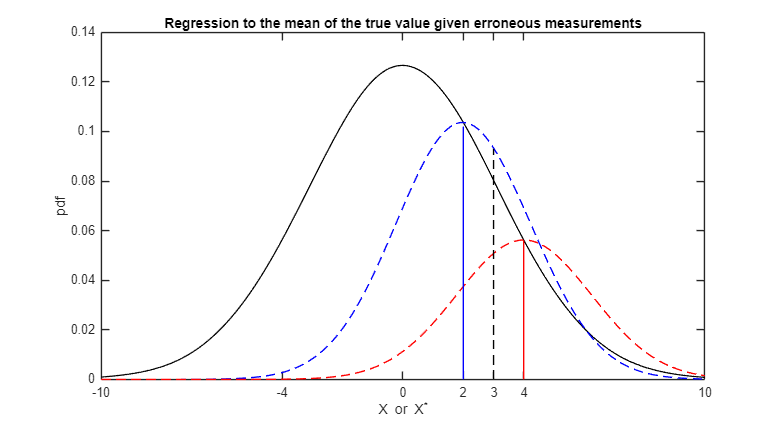

f10=figure;
resize_figure(f10,120,220);
plot(xbin,fX,'k','LineWidth',1);
hold on;
plot(xbin,fX(xbin==im).*fX_noise_2./(max(fX_noise_2)),'--b');
% plot(xbin,fX(xbin==3).*fX_noise_3./(max(fX_noise_2)));
plot(xbin,fX(xbin==fm).*fX_noise_4./(max(fX_noise_4)),'--r');
plot([3,3],[0,0.093],'--k');
hold on;
plot([2,2],[0,0.102],'b');
hold on;
plot([4,4],[0,0.056],'r');
title('Regression to the mean of the true value given erroneous measurements');
xlabel('X or X^*');
ylabel('pdf');
set(gca,'XTick',[-10,-4,0,2,3,4,10]);

if setExportFig
export_fig([outputFolder,'FigureS10.png'], ...
    '-r600','-png','-nocrop',f10);
export_fig([outputFolder,'FigureS10.pdf'], ...
    '-r600','-pdf','-nocrop',f10);
end
toc

Elapsed time is 0.546564 seconds.


# Uncorrelated Gaussian Errors

## Fig 2b: Normal distribution

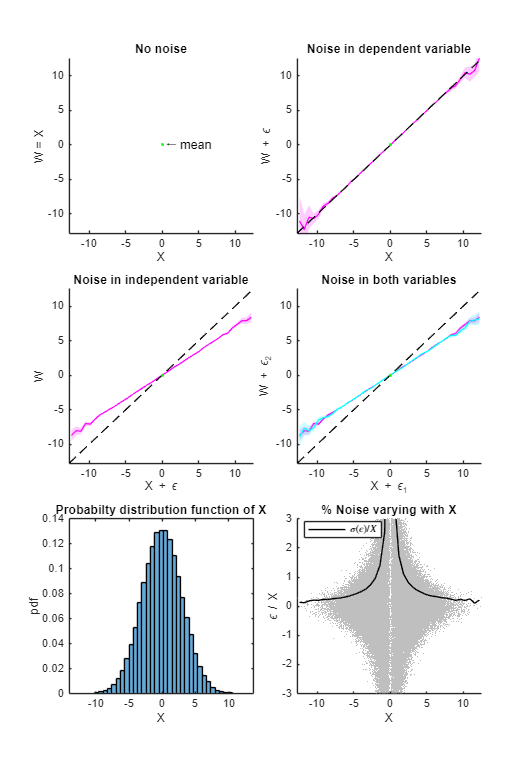

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 2;

X = random('Normal',0,3,1,nSamples);
W = X;

W1 = W + noiseAmp.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EWgX1 = create_curve(W',X1',XBin);

X1 = X + noiseAmp.*random('Normal',0,1,1,nSamples);
EW1gX1 = create_curve(W1',X1',XBin);

f2 = figure;
resize_figure(f2,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');


if setExportFig
export_fig([outputFolder,'FigureS2.png'], ...
    '-r600','-png','-nocrop',f2);
export_fig([outputFolder,'FigureS2.pdf'], ...
    '-r600','-pdf','-nocrop',f2);
end

# Correlated Gaussian Errors

## Fig 2c: Log-normal distribution

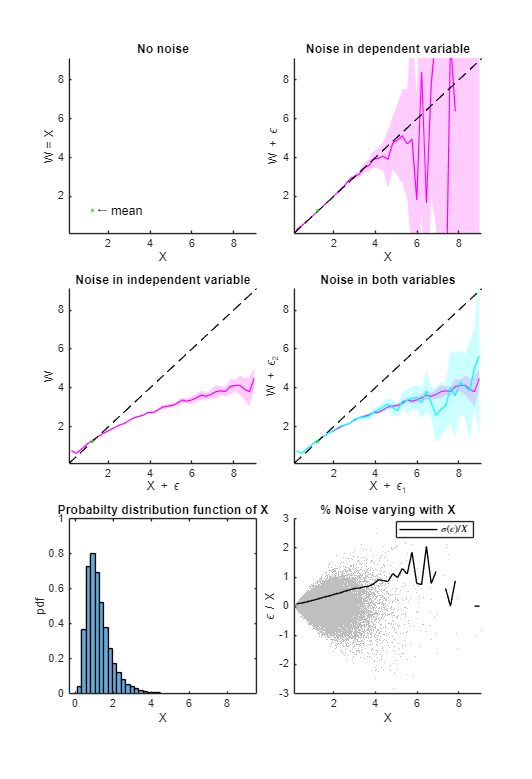

nSamples  = 100000;
nEnsembles = 1;

noiseAmp = 0.2;

X = random('Lognormal',0.1,0.5,1,nSamples);
W = X;

W1 = W + noiseAmp.*W.^2.*random('Normal',0,1,1,nSamples);
X1 = X + noiseAmp.*X.^2.*random('Normal',0,1,1,nSamples);

XBin = linspace(min(X),max(X),40);
EWgX = create_curve(W',X',XBin);
EW1gX = create_curve(W1',X',XBin);


EWgX1 = create_curve(W',X1',XBin);

EW1gX1 = create_curve(W1',X1',XBin);

f6 = figure;
resize_figure(f6,220,150);
plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,'linear');

if setExportFig
export_fig([outputFolder,'FigureS6.png'], ...
    '-r600','-png','-nocrop',f6);
export_fig([outputFolder,'FigureS6.pdf'], ...
    '-r600','-pdf','-nocrop',f6);
end


## **Functions**

function plot_type0(X,W,X1,W1,EWgX1,EW1gX,EW1gX1,XBin,Scale)
    tiledlayout(3,2,'TileSpacing',"compact");
    
    nexttile
    scatter(X,W,0.1,0.5.*[1 1 1],'filled');
    set(gca,'XScale',Scale,'YScale',Scale);
    hold on;
    plot(mean(X),mean(W),'.g');
    text(mean(X),mean(W),' 🠐 mean',"HorizontalAlignment","left");
    title('No noise');
    xlabel('X');
    ylabel('W = X');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    %% Regression curve with noise only on W
    nexttile
    
    scatter(X,W1,0.1,[0.7 0.7 0.7],'filled',"o");
    hold on;
    plot_curve(EW1gX,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('Noise in dependent variable');
    xlabel('X');
    ylabel('W + \epsilon');
    
    %% Regression curve with noise only on X
    nexttile
    
    scatter(X1,W,0.1,0.5.*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('X vs. X+\epsilon')
    title('Noise in independent variable');
    xlabel('X + \epsilon');
    ylabel('W');
    %% Regression curve with noise in X & W
    
    nexttile
    
    scatter(X1,W1,0.1,0.5.*[1 1 1],'filled');
    hold on;
    plot_curve(EWgX1,'m');
    hold on;
    plot_curve(EW1gX1,'c');
    hold on;
    plot(XBin,XBin,'LineStyle','--','Color','k','LineWidth',1);
    plot(mean(X),mean(W),'.g');
    ylim([min(W),max(W)]);
    xlim([min(X),max(X)]);
    set(gca,'XScale',Scale,'YScale',Scale);
    title('X+\epsilon vs. X+\epsilon')
    title('Noise in both variables');
    xlabel('X + \epsilon_1');
    ylabel('W + \epsilon_2');
    
    nexttile
    histogram(X,'BinEdges',XBin,'Normalization',"pdf");
    xlabel('X');
    ylabel('pdf');
    title('Probabilty distribution function of X')
    
    ax2=nexttile;
    scatter(X,(X1-X)./X,0.5,0.5.*[1 1 1],'filled');
    EegX = create_curve((X1'-X'),X',XBin);
    hold on;
    p1=plot(EegX.XBins,EegX.stdYgX./abs(EegX.XBins),'k');
    legend(ax2,p1,'$\sigma(\epsilon)/X$','interpreter','latex','Location','best');
    ylim([-3 3]);
    xlim([min(X),max(X)]);
    xlabel('X');
    ylabel('\epsilon / X');
    title('% Noise varying with X')
end

function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX, 'Color', color,'LineWidth',1);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function curve = create_curve(Y, X, Ei)
% Y - first variable, X - second variable, Ei - bin array
if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

function resize_figure( figureHandle, vert, horz )
%% resize_figure.m Resizes figure into a standard paper size
%--------------------------------------------------------------------------
% Input
%------
% figureHandle
% vert - Vertical page size in mm (Default Letter Size)
% horz - Horizontal page size in mm (Default Letter Size)

if nargin<3 || isempty(horz)
    horz = 215.9;
end
if nargin<2 || isempty(vert)
    vert = 279.4;
end

% Centimeter Units
X = horz/10;
Y = vert/10;
xMargin = 0;
yMargin = 0;
xSize = X - 2*xMargin;
ySize = Y - 2*yMargin;

% Figure size displayed on screen
movegui(figureHandle, 'center');
set(figureHandle,'color','w');
set(figureHandle, 'Units', 'centimeters', 'Position', [0 0 xSize ySize])
end

function B = interp_nans(A)
%% interp_nans.m This function removes nan by interpolating along altitude
%--------------------------------------------------------------------------
% Input
%------
% A - Input altitude vs. time matrix [nh x nT]
%--------------------------------------------------------------------------
% Output
%-------
% B - Interpolated altitude vs. time matrix, along the altitude directon
%     with nans removed [nh x nT]
%--------------------------------------------------------------------------
% Modified: 17th Jan 2018 
% Created : 25th Sep 2016
% Author  : Nithin Sivadas
% Ref     : 
%--------------------------------------------------------------------------
     
	x=1:1:size(A,1);
    
	for ty=1:1:size(A,2)
	
	    y=A(:,ty);
	    xi=x(find(~isnan(y)));
	    yi=y(find(~isnan(y)));
	   
        if sum(isnan(y))< size(A,1)-2
        B(:,ty)=interp1(xi,yi,x,'linear','extrap');
        else
        B(:,ty)=A(:,ty);
        end
	
    end

	[isThereNAN, totalNAN] = check_nan(B);

end

function [isThereNAN, totalNAN] = check_nan(thisArray)
%% check_nan.m Check if there is any nan values in the given array
%--------------------------------------------------------------------------
% Input
%------
% thisArray : An array or a matrix
%--------------------------------------------------------------------------
% Output
%-------
% isThereNAN : A boolean variable, True => there is nan values in the
%              array, and False => there is no nan values in the array
% totalNAN   : The total number of NAN values
%
%--------------------------------------------------------------------------
% Modified: 22nd Sep 2016 
% Created : 22nd Sep 2016
% Author  : Nithin Sivadas
% Ref     :
%--------------------------------------------------------------------------

thisArrayNAN = isnan(thisArray);
totalNAN = sum(thisArrayNAN(:));

    if totalNAN>0
        isThereNAN = true;
    else
        isThereNAN = false;
    end

    if isThereNAN==true
        warning(['There are ',num2str(totalNAN),...
        ' nan values in your data. The results may not be accurate.']);
    end
    
end

%%